clear;
clear mex; % resets values inside PID
addpath('open_loop_valve_control_cpp');
addpath('closed_loop_valve_control_cpp');

**CONSTANTS AND SIMULATED DATA BASELINE**

Consts = [A_t, c_star, gfts, IPA/OX_ratio]

simData = [OX_Tank_Pressure, IPA_Tank_Pressure, OX_Valve_Temp, OX_cv_Temp , IPA_Valve_Temp, IPA_cv_Temp]

consts = [1.69 4998.0654 32.1740 1.2];
simData = [820 820 90 90 280 280];

% Delays and noise
actuator_delay = 0.1131;
noise_var_actuators = 0.1039 / 50;
noise_var_outputs = 1;
noise_var_mdot = 1e-10;
%model_error = 0.9 + 0.2*rand;
ox_mdot_error = 1.05;
ipa_mdot_error = 0.95;
cp_error = 1.1;
timeDelta = 1/100;

**CONVERSION FACTORS**

IN3_TO_GAL, PER_SEC_TO_PER_MIN, LB_TO_TON, PER_IN3_TO_PER_M3

conversionFactors = [0.004329 60 0.000453592 61023.7];

**LOOK-UP ARRAYS**

tempArray = [55, 60, 65, 70, 75, 80, 85, 90, 95, 100, 105, 110, ...
    115, 120, 125, 130, 135, 140, 145, 150];
oxDensityArray = [0.04709027778, 0.04631539352, 0.04550925926, 0.0446880787, 0.04385474537,...
    0.04300810185, 0.04214525463, 0.04126099537, 0.04035127315, 0.03941087963, 0.03843229167,...
    0.03740856481, 0.03632986111, 0.03518287037, 0.03394965278, 0.03260416667, 0.03110532407,...
    0.02938020833, 0.0272806713, 0.0244033564];
oxPressureArray = [0.0259, 0.10527, 0.33866, 0.90826, 2.1099, 4.369, 8.2426, 14.41, 23.653,...
    36.84, 54.901, 78.814, 109.59, 148.27, 195.93, 253.68, 322.72, 404.33, 500.05, 611.86];
ipaDensityArray = 0.02836;
ipaPressureArray = 0.638;
thrustArray = [220, 550];
c_fArray = [1.12, 1.3];
subCritVArray = [0.000, 0.070, 0.161, 0.378, 0.670, 1.000, 1.450, 2.050, 2.780, 3.710, 4.960];
valveAngleArray = [0, 9, 18, 27, 36, 45, 54, 63, 72, 81, 90];
fuelData = [oxDensityArray; oxPressureArray];


**TESTS**

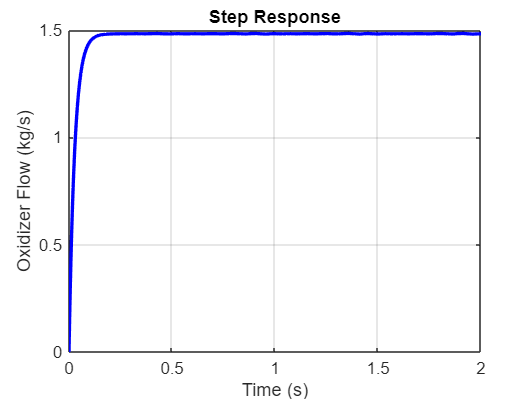

tspan = [0 2];

% Define state vector and initials
%x = [mdot_ox; mdot_ipa; Pc];
x0 = [0 0 0];

% Time constants
tau_mdot = 0.11 / 4;
tau_pc = 0.5 / 4;

% Step angles
angle_ox = 50;
angle_ipa = 50;

% Simulate system
[t, x] = ode45(@(t, x) NonLinearModel(x, angle_ox, angle_ipa, ...
     consts, simData, fuelData), tspan, x0);

% Plots step response
figure;
plot(t, x(:,1), 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Oxidizer Flow (kg/s)');
title('Step Response');
grid on

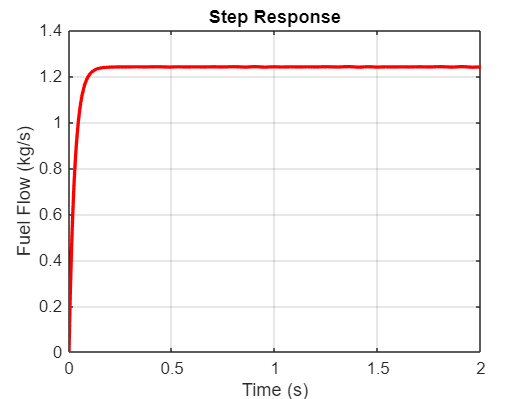


figure;
plot(t, x(:,2), 'r', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Fuel Flow (kg/s)');
title('Step Response');
grid on

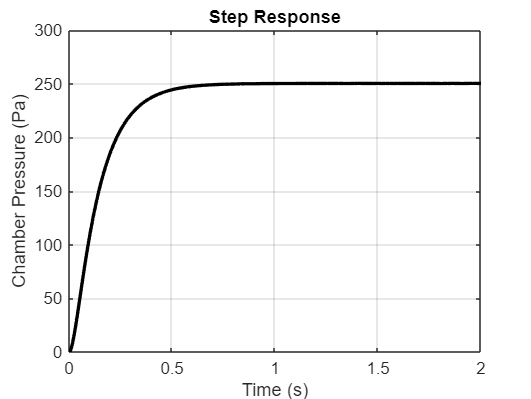


figure;
plot(t, x(:,3), 'k', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Chamber Pressure (Pa)');
title('Step Response');
grid on